clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;
% Adjusts the A matrix as described in Examination 1
for i=1:4
    param.model.A(3*i,3*i) = -1;
end

## Control

param.ctrl.Ks = control.DesignProcedure1(param,0); 

Evaluation of design procedure 1 
Q is positive definite


ans =     0.2880    0.2892    0.2892    0.2892    0.7270    0.7275    0.7275    0.7275    1.3453    1.3453    1.3453    1.3493


R is positive definite


ans =    27.1436   37.5516   43.0021  114.6580  115.4977  115.6633  118.6280  124.1419  242.7167  318.9311  367.7529  952.4013


Gamma is found to be:


ans = 85.5366

Eigenvalues of the decoupled systems are all negative 


ans =   -1.3254 + 3.7937i  -1.3254 - 3.7937i  -0.9222 + 0.0000i  -1.3274 + 3.8404i  -1.3274 - 3.8404i  -0.9221 + 0.0000i  -1.3254 + 3.7937i  -1.3254 - 3.7937i  -0.9222 + 0.0000i  -1.3254 + 3.7937i  -1.3254 - 3.7937i  -0.9222 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -0.7753 + 5.2359i  -0.7753 - 5.2359i  -0.4258 + 5.9406i  -0.4258 - 5.9406i  -0.3169 + 6.1623i  -0.3169 - 6.1623i  -0.2890 + 6.1948i  -0.2890 - 6.1948i  -0.9280 + 0.0000i  -0.9296 + 0.0000i  -0.9297 + 0.0000i  -0.9300 + 0.0000i


% param.ctrl.Ks = control.DesignProcedure2(param,0,1);

## Simulate decoupled system

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode23s(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end

## Simulate coupled system

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
[t,x] = ode23s(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0);

-1.544870, 0.000000, 0.000000, 0.000000, 
-3.211885, 0.000000, -0.000000, -0.000000, 
-4.918400, 0.000000, 0.000000, 0.000000, 
-8.775002, 0.000000, 0.000000, 0.000000, 
-11.598181, 0.000000, -0.000000, 0.000000, 
-13.340497, 0.000000, -0.000000, -0.000000, 
-13.340497, 0.000000, -0.000000, -0.000000, 
-13.340497, -0.000000, 0.000000, -0.000000, 
-13.340497, 0.000000, 0.000000, -0.000000, 
-13.340497, 0.000000, 0.000000, 0.000000, 
-13.340497, -0.000000, -0.000000, -0.000000, 
-13.340497, -0.000000, -0.000000, -0.000000, 
-13.340497, -0.000000, -0.000000, -0.000000, 
-13.340497, 0.000000, 0.000000, 0.000000, 
-13.340498, -0.000000, 0.000000, -0.000000, 
-13.340497, -0.000000, 0.000000, 0.000000, 
-13.340497, 0.000000, -0.000000, -0.000000, 
0.000000, -0.754436, 0.000000, 0.000000, 
0.000000, -0.754436, -0.000000, 0.000000, 
-14.316499, 0.000000, 0.000000, 0.000000, 
0.000000, -0.754436, 0.000000, -0.000000, 
0.000000, -0.754436, 0.000000, -0.000000, 
-14.316499, 0.000000, -0.000000, 0.

0.000000, -41.836821, 0.000000, -0.000000, 


0.000000, -41.836821, 0.000000, -0.000000, 


0.000000, -41.836821, 0.000000, -0.000000, 


0.000000, -41.836821, 0.000000, -0.000000, 


0.000000, -41.836821, 0.000000, -0.000000, 


0.000000, -41.836821, 0.000000, -0.000000, 
-31.539883, -71.918530, 0.000000, 0.000000, 
-31.539883, -71.918530, 0.000000, 0.000000, 
-31.539883, -71.918530, -0.000000, 0.000000, 
-31.539883, -71.918530, 0.000000, 0.000000, 
-31.539883, -71.918530, 0.000000, 0.000000, 
-31.539883, -71.918530, 0.000000, 0.000000, 
-31.539883, -71.918530, 0.000000, 0.000000, 
-31.539883, -71.918530, 0.000000, 0.000000, 
0.000000, -103.826674, -0.000000, 0.000000, 
0.000000, -103.826674, -0.000000, 0.000000, 
0.000000, -103.826674, -0.000000, 0.000000, 
0.000000, -103.826674, 0.000000, 0.000000, 
0.000000, -103.826674, -0.000000, 0.000000, 
0.000000, -103.826674, 0.000000, -0.000000, 
0.000000, -103.826674, 0.000000, 0.000000, 
0.000000, -103.826674, -0.000000, 0.000000, 
0.000000, -103.826692, -0.000000, -0.000000, 
0.000000, -103.826687, -0.000000, -0.000000, 


-41.131029, 0.000000, 0.000000, 0.000000, 
0.000000, -103.826674, -0.000000, 0.000000, 
-52.817703, -134.182828, -0.000000, 0.000000, 
-211.039825, 0.000000, -0.000000, -0.000000, 
-758.062120, 0.000000, -0.000000, 0.000000, 
-758.062120, 0.000000, -0.000000, 0.000000, 
-758.062120, 0.000000, -0.000000, 0.000000, 
-758.062119, 0.000000, -0.000000, -0.000000, 
-758.062119, 0.000000, -0.000000, -0.000000, 
-758.062120, 0.000000, -0.000000, 0.000000, 
-758.062120, 0.000000, -0.000000, 0.000000, 
-758.062120, 0.000000, 0.000000, -0.000000, 
0.000000, -1925.848963, 0.000000, 0.000000, 
-758.062120, 0.000000, -0.000000, 0.000000, 
-758.062120, 0.000000, -0.000000, 0.000000, 
-758.062232, 0.000000, 0.000000, 0.000000, 
-758.062243, 0.000000, 0.000000, -0.000000, 
-758.062120, 0.000000, -0.000000, 0.000000, 
-1080.624259, 0.000000, 0.000000, 0.000000, 


-1464.575008, 0.000000, 0.000000, 0.000000, 
-7503.824974, -19063.389623, 0.000000, 0.000000, 
-5010.292592, 0.000000, -0.000000, -0.000000, 
-6622.679651, 0.000000, 0.000000, -0.000000, 
-6622.679651, 0.000000, 0.000000, -0.000000, 
-6622.679651, 0.000000, 0.000000, -0.000000, 
-6622.679650, 0.000000, 0.000000, 0.000000, 
-6622.679650, 0.000000, -0.000000, -0.000000, 
-6622.679651, 0.000000, 0.000000, -0.000000, 
-6622.679651, 0.000000, 0.000000, -0.000000, 
-6622.679651, 0.000000, 0.000000, 0.000000, 
-6622.679651, 0.000000, -0.000000, 0.000000, 
-6622.679651, 0.000000, 0.000000, -0.000000, 
-6622.679651, 0.000000, 0.000000, -0.000000, 
-6622.680522, 0.000000, 0.000000, 0.000000, 
-6622.680784, 0.000000, 0.000000, -0.000000, 
-6622.679651, 0.000000, 0.000000, -0.000000, 
-8567.030738, -21764.452853, 0.000000, 0.000000, 
-7324.198493, 0.000000, 0.000000, -0.000000, 
-8477.211971, -21536.269206, -0.000000, -0.000000, 
-6963.386225, 0.000000, 0.000000, 0.000000, 
-7312.774465, 0.000000,

coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

## Plot simulation results

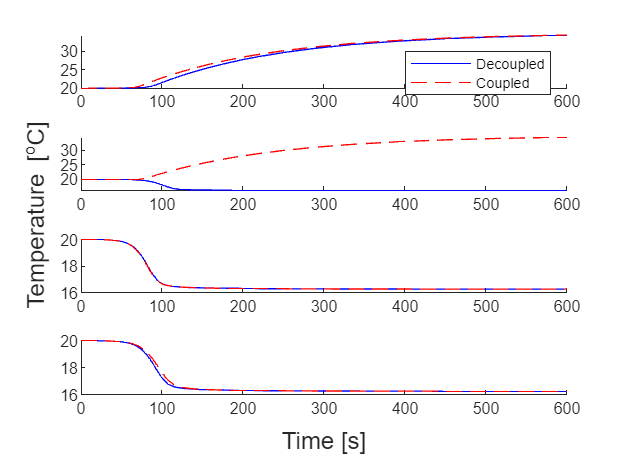

figure()
f = tiledlayout('vertical');
for i=1:4
    nexttile
    hold on
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15,'blue')
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15,['red','--'])
    if i==1
        legend('Decoupled','Coupled',Location='northeast')
    end
    hold off
end
xlabel(f,'Time [s]')
ylabel(f,'Temperature [^{o}C]')
% saveas(gcf,'../Images/Examination_Examination1_DP1','epsc')
% saveas(gcf,'../Images/Examination_Examination1_DP2','epsc')